## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

### **Section 04 - Example 02 - Active Morphing Truss**

Here, we hope to demonstrate how to integrate active truss into the simulation. Active morphing structures are those that change their shapes when certain stimulus is applied to the structural members. For example. in the following truss system, the black trusses are normal ones that does not generate large deformation. The red trusses (the two on the left and on the right) are the active ones that can shrink when heat is applied to them. Here, we want to see what will happen if 30K of heating is applied to the left trusses. Systems like this is widely used in robotics, space structures, and responsitve metamaterials. 

 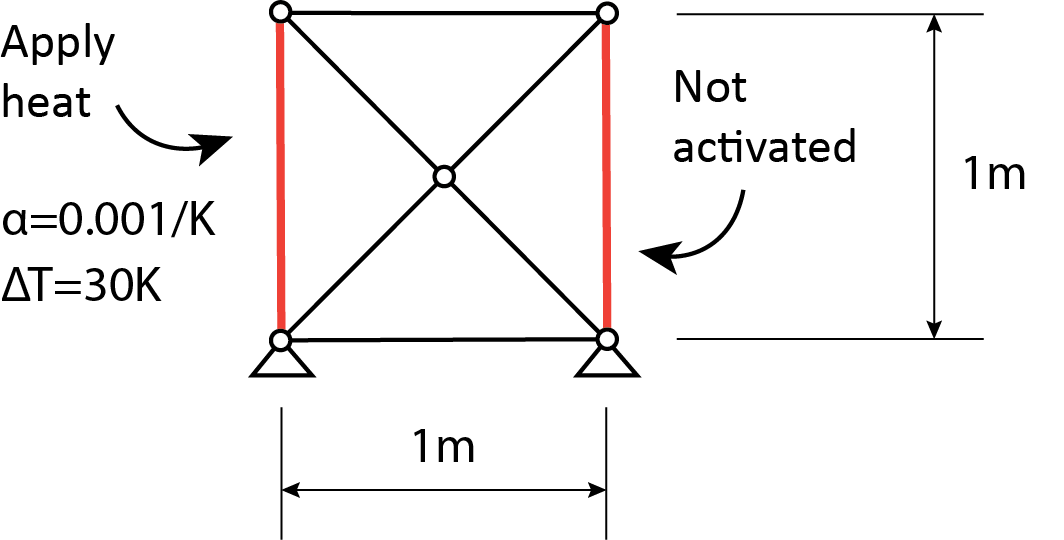

For this structure above, the length is $L=1m$; The cross section area of all truss elements are $\textrm{barA}=0\ldotp 0001m^{2\;} ;$ the Young's modulus of the normal bar is $\textrm{barE}=2\times {10}^{9\;} \textrm{Pa}$. For the active bars, we have the Young's modulus being $\textrm{activeBarE}=2\times {10}^{6\;} \textrm{Pa}$, thermal expansion being $\textrm{alpha}=0\ldotp 001\;\textrm{strain}/K$, and the elevated temperature is $\textrm{deltaT}=30\;K\ldotp$ The definition of these properties are done below.

%% Initialize the system
L=1; % Length of each span

% Property of normal truss
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% Property of active truss
activeBarE=2*10^6;
deltaT=30;
alpha=0.001;

Here, we will set up the node and the two bars in the assembly object. We use the vectorized bar element to represent the normal bar and use the central-difference based element to represents the active bars (Just like Section 02). Please note that due to the formulation, the current vectorized elements do not support the application of active strain, so we can only use the CD elements for active bars. Here, we wan to briefly compare the assembly set up of this Example 02 with the Exmaple 01 we previously finished. The one major difference here is that the assembly class for active truss has two element types - one standard bars and one active bars (actBar). Thus, when solving the forces and stiffness, we need to compute the global forces from both the normal bars and the active bars and then sum them up. 

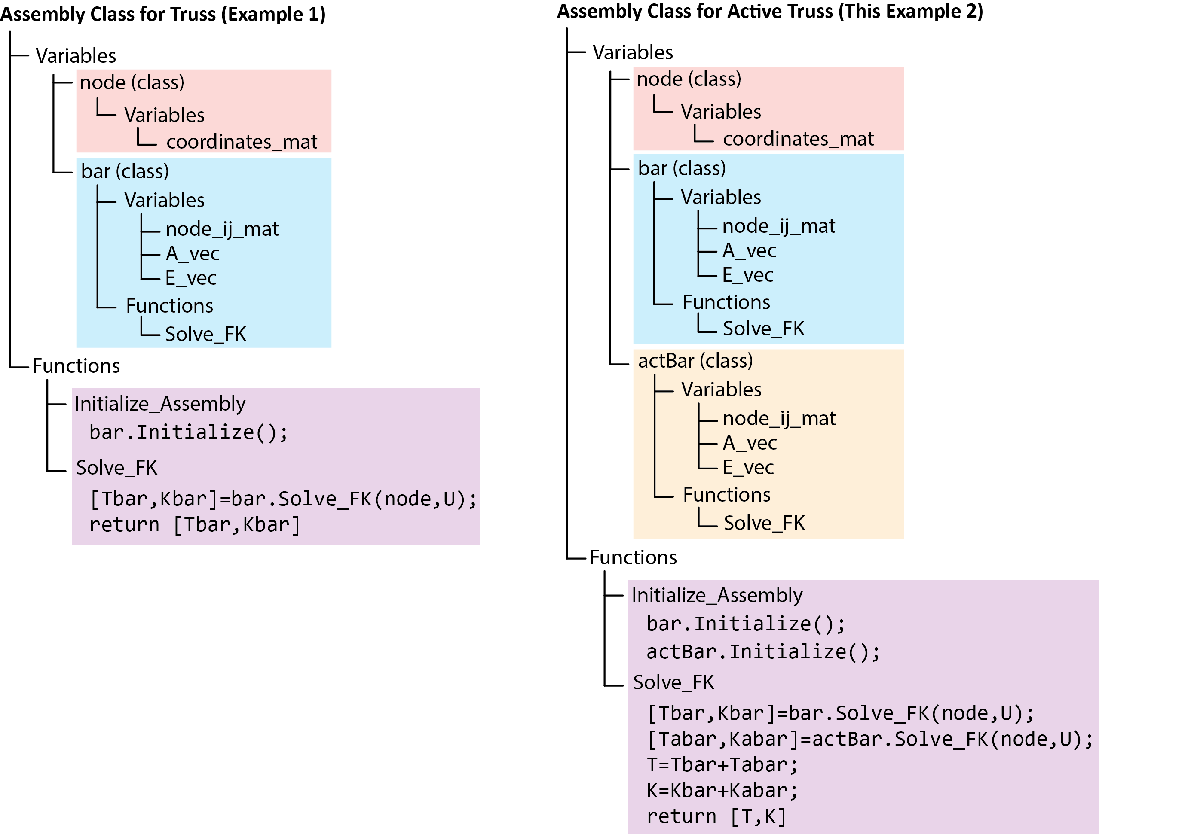

% Define the node object
node=Elements_Nodes;
% Create the bar object
bar=Vec_Elements_Bars;
actBar=CD_Elements_Bars;

% Create tje truss Assembly
assembly=Assembly_Truss;
% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.actBar=actBar;

After seting up the objects, we will define the nodal coordinates. Here, a total of 5 node is needed and they are stored in the matrix "coordinates_mat" in the node object. 

%% Define the nodal coordinates
% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0 0 0; 
                      L 0 0;
                      0 0 L;
                      L 0 L;
                      0.5*L 0 0.5*L;
                      ];

Here the nodes are located in the XZ plane. This is why the second column (Y-axis) is all zero for the matrix. Now, to check if we entered the correct nodal coordinates or not, we can use the following plotting function. Again, "plots" is an object of the class "Plot_Truss". Here, we set the assembly variable in the object to be the "assembly" object we just created. 

% Set up the plotting function for inspection
plots=Plot_Truss();
plots.assembly=assembly;

Before plotting, we set a couple variable for the plotting function. This include the range we want to plot and the angles we hope to look into the object. Here, 0 for the viewAngle1 and viewAngle2 will give us the XZ plane. We next plot the place of this node. 

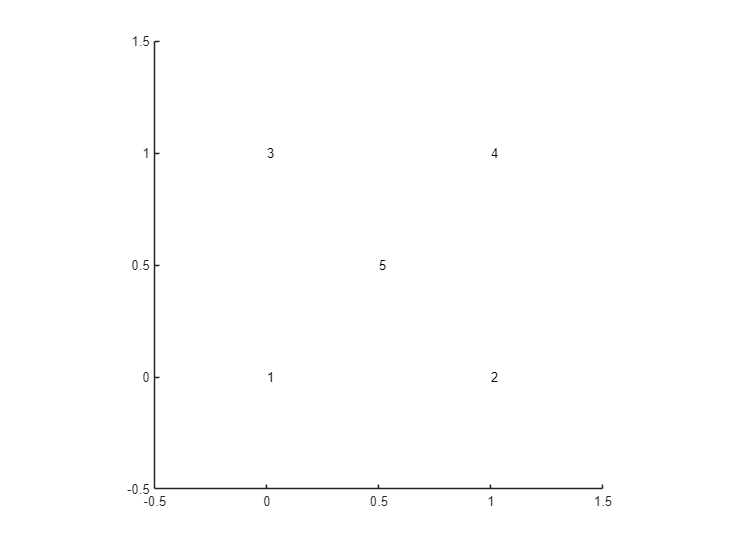

% We will plot for the truss assembly
plots.displayRange=[-0.5;1.5;-1;1;-0.5;1.5]; 
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

% Plot the nodal coordinates for inspection
plots.Plot_Shape_Node_Number()

Looking good! Now that have the nodes defined, we can further define the two type of bar (truss) elements. Here we need to add rows to the matrix "node_ij_mat" in the bar object. Each row of the matrix gives the two node of one bar. For instance, the first row of the "node_ij_mat" matrix is used to define the first bar element, and this element connects node 1 and node 2. 

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,2;
                 2,5;
                 1,5;
                 3,4;
                 3,5;
                 4,5;]; % 6 bars

% Next we design the active truss
actBar.node_ij_mat=[1 3;
                    2 4];

After setting how how bars are connected, we will continue to define the properties of the bar (truss) element - the cross section areas of each truss and the Young's modulus of each truss. This is done with the following code.

% Define the normal bars
bar.A_vec=barA*ones(6,1);
bar.E_vec=barE*ones(6,1);

% Define the active bars
actBar.A_vec=barA*ones(2,1);
actBar.E_vec=activeBarE*ones(2,1);

Now that we have defined all the structure, we can initialize the full assembly and plot the bar (truss) we just defined. In addition to plotting the shape of the truss, we also have the bar number of each truss shown in the figure.

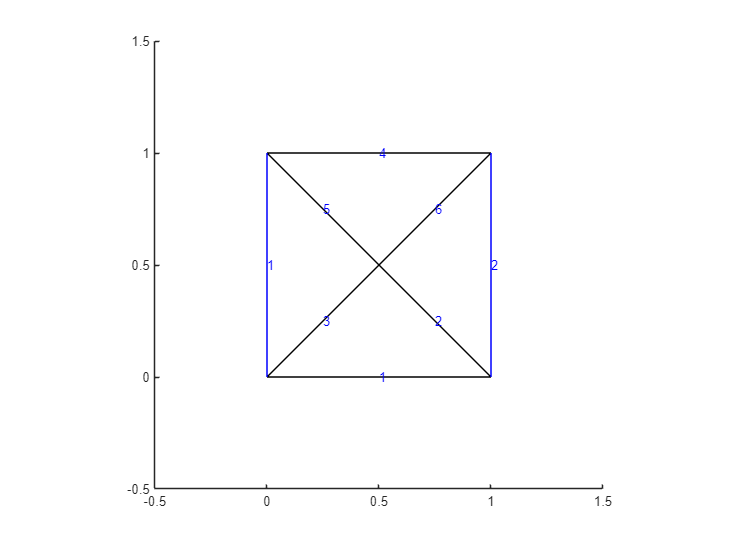

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Set up the 
plots.Plot_Shape_Bar_Number()

With the structure setted up, we can now define the loading situation. We will set up a Newton-Raphson solver to solve for the responses in the structure. Instead of using the loading solver demonstrated in Example 01, we use the "TrussAction" solver. The principle is still the same, we apply the truss action by gradually changing the target stress free length of the active truss "L0". Each time we change "L0", the equilibrium position is tracked using the second-order Newton's method. 

Here, "nr" is the object created based on the solver class "Solver_NR_TrussAction". We set the assembly to be our truss and then set up the support. Here, each row in the "supp" matrix represents one support. The first column is used to represent the node number while the remaining three columns are used to represent if XYZ deformation is restricted or not (1 means support provided, 0 means free to move). Because this is a 2D problem, the Y-axis deformation is all restricted. 

%% Set up the self actuation solver
nr=Solver_NR_TrussAction;
nr.assembly=assembly;
nr.supp=[1,1,1,1;
         2,1,1,1;
         3,0,1,0;
         4,0,1,0;
         5,0,1,0;];

Next, we will set up the target L0 vector. Basically, the target stress free length of the bar is the original length of the bar times its engineering strain. The engineering strain can be found by multiplying the thermal expansion coefficient with the elevated temperature of the active truss. 

% Set up the actuation
nr.targetL0=actBar.L0_vec;
% Find the active strain due to the applied heating
deltaStrain=deltaT*alpha;
% Find the extention
% Please note that we are only applying actuation in the left active truss
% Thus, only the first element of the targetL0 vector is altered
nr.targetL0(1)=nr.targetL0(1)*(1-deltaStrain);

We will achieve the application of actuation 10-steps, each with a maximum of 30 iteration.

% Set up the total loading step
nr.increStep=10;
% Set up the maximum iteration
nr.iterMax=30;

Now that everything is creatd, we can ask the program to find the deformation history Uhis for us. This is done by asking the solver object "nr" to perform the "Solve()" function. 

% Solve for the deformation history
Uhis=nr.Solve();

Self Assemble Analysis StartIcrement = 1
	Iteration = 1, R = 6.018054e-01 
	Iteration = 2, R = 2.674924e+00 
	Iteration = 3, R = 4.406337e-05 
	Iteration = 4, R = 2.932672e-08 
Icrement = 2
	Iteration = 1, R = 6.045235e-01 
	Iteration = 2, R = 2.694848e+00 
	Iteration = 3, R = 9.143534e-05 
	Iteration = 4, R = 5.554736e-08 
Icrement = 3
	Iteration = 1, R = 6.072565e-01 
	Iteration = 2, R = 2.731248e+00 
	Iteration = 3, R = 7.747765e-05 
	Iteration = 4, R = 6.608723e-08 
Icrement = 4
	Iteration = 1, R = 6.100047e-01 
	Iteration = 2, R = 2.779249e+00 
	Iteration = 3, R = 2.886249e-05 
	Iteration = 4, R = 3.432430e-08 
Icrement = 5
	Iteration = 1, R = 6.127681e-01 
	Iteration = 2, R = 2.785470e+00 
	Iteration = 3, R = 1.385495e-04 
	Iteration = 4, R = 3.154197e-07 
Icrement = 6
	Iteration = 1, R = 6.155467e-01 
	Iteration = 2, R = 2.803638e+00 
	Iteration = 3, R = 2.519548e-04 
	Iteration = 4, R = 1.974476e-07 
Icrement = 7
	Iteration = 1, R = 6.183407e-01 
	Iteration = 2, R = 2.893232e+0

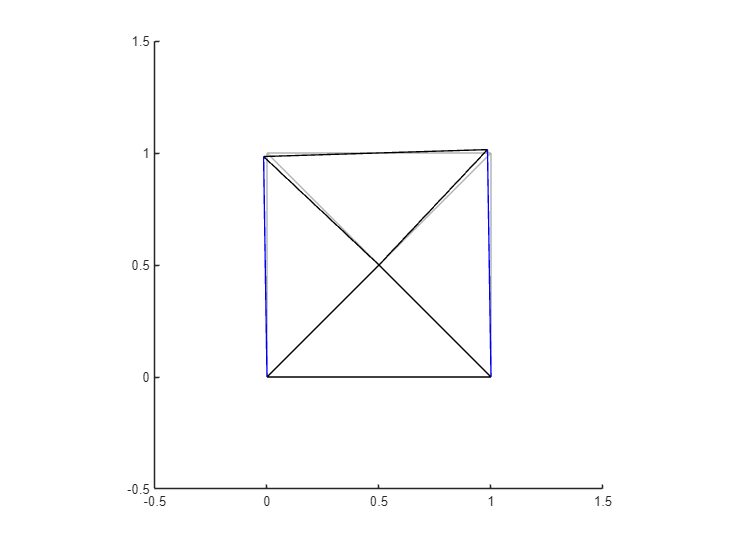

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));

Looking good! This is exactly what we expect to see. We have applied heating to the left truss so the left truss should contract. The contraction will turn the triangle normal truss towards the left. Now let's see what will happen if we further apply the additional 20N to the top left node of the structure. This will create the following system as shown in the figure. Please note that if we do not initialize the assembly again, the loading will just continue from the actuation stage. This way, we can create multiple sequence of loading, which is needed for the simulation of active structures in general. 

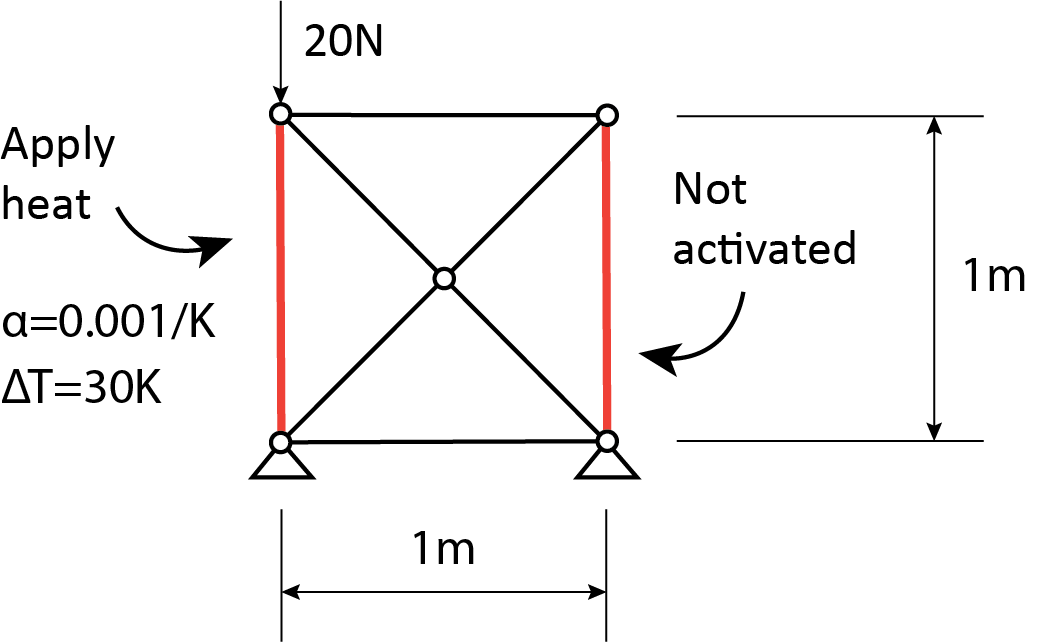

%% Set up the loading solver
nrLoad=Solver_NR_Loading();
nrLoad.assembly=assembly;
nrLoad.supp=[1,1,1,1;
         2,1,1,1;
         3,0,1,0;
         4,0,1,0;
         5,0,1,0;];

% Apply load on the left top node
nrLoad.load=[3,0,0,-2];

% Set up the total loading step
nrLoad.increStep=10;
% Set up the maximum iteration
nrLoad.iterMax=30;

% Solve for the additional loading
UhisLoad=nrLoad.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 3.980184e-02
    Iteration = 2, R = 8.496473e-04
    Iteration = 3, R = 1.192437e-03
    Iteration = 4, R = 1.684717e-05
    Iteration = 5, R = 5.511719e-08
Icrement = 2
    Iteration = 1, R = 1.040404e-02
    Iteration = 2, R = 1.610472e-04
    Iteration = 3, R = 3.600921e-05
    Iteration = 4, R = 5.681016e-07
Icrement = 3
    Iteration = 1, R = 1.067538e-02
    Iteration = 2, R = 1.082198e-04
    Iteration = 3, R = 2.592943e-05
    Iteration = 4, R = 2.970130e-07
Icrement = 4
    Iteration = 1, R = 1.086373e-02
    Iteration = 2, R = 1.184834e-04
    Iteration = 3, R = 3.104000e-05
    Iteration = 4, R = 5.227130e-07
Icrement = 5
    Iteration = 1, R = 1.126992e-02
    Iteration = 2, R = 8.225064e-05
    Iteration = 3, R = 1.534632e-05
    Iteration = 4, R = 1.508072e-07
Icrement = 6
    Iteration = 1, R = 1.122750e-02
    Iteration = 2, R = 1.507522e-04
    Iteration = 3, R = 4.414233e-05
    Iteration = 4, R = 3.472082e-07


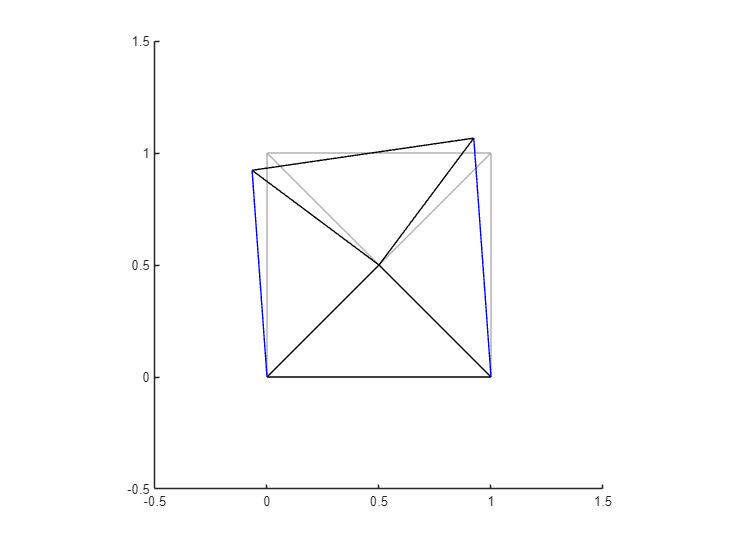

% Plot the deformed shape with additional loading
plots.Plot_Deformed_Shape(squeeze(UhisLoad(end,:,:)));

Looking good!

Indeed, we have developed more rotation by compressing the left top node. 

#### **Practice Problems:**

Now, to practice, please consider working out the following problems. 

#### **Problem 01 **

Please simulate the deployment of the following structure. Assuming that all three active truss are actuated at the same time. What is the deformed configuration?